# **讨论是否生成AgCl**

# **AgCl沉淀问题**

**视野中Ag颗粒分布稀疏，那么被氧化成Ag+后相应的浓度也不会很大。此时[Ag+][Cl-]或许有机会小于Ksp，即此时不会产生AgCl的沉淀。Ag+在水溶液中的扩散系数约为1.648cm2s-1，那么其1s内大约能扩散40um，可以认为溶液中Ag+浓度是均匀分布的。**

V = 4*pi/3*(40e-7)^3;    % 单个银颗粒体积，单位立方厘米
M = 107.8;              % 银相对原子质量，单位g/mol
rho = 10.5;             %银密度，单位g/cm3
n = V*rho/M              % 一个银颗粒中包含的原子数n =v*rho/M，单位mol/个

n = 2.6112e-17

V_filed = 33*44*50*(1e-5)^3    % 相机视野对应的溶液体积，单位L

V_filed = 7.2600e-11

n_particle = 50;        % 视野中分布的颗粒数目
c = n/V_filed*n_particle% 颗粒全部溶解对应的Ag+的浓度

c = 1.7983e-05

Ksp = 1.77e-10;         % AgCl的溶度积
c_FeCl3 = Ksp/c/3       % FeCl3浓度低于此值，则AgCl无法沉淀

c_FeCl3 = 3.2808e-06

氧化物浓度相同，反应速度不同同样会导致无法沉淀。对于AgNC而言，其反应速度相较于AgNS而言慢很多。实验发现，同样FeCl3浓度下，反应之后AgNC没有AgCl存留，而AgNPs有AgCl存留。总结：

1、相同浓度FeCl3，AgNC氧化速度更慢，反应之后无AgCl，AgNS氧化速度更快，反应后有AgCl留存。

2、对于相同的颗粒，即便反应后无AgCl留存，只要表面有AgCl，反应过程中就会有闪烁。只是如果AgCl能够积累下来，闪烁次数会更多。

# **AgNPs-1mM**

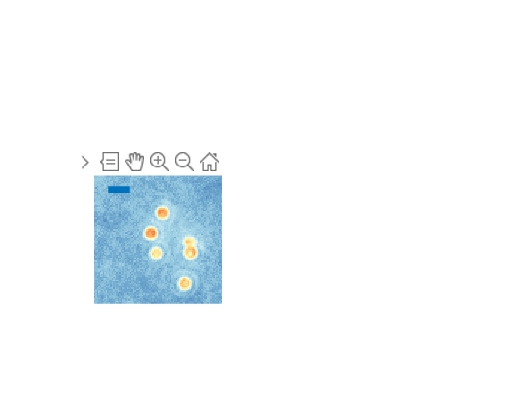

% 反应前的数据
m = [280 365 20 105];
savepath = "D:\工作汇总\文章\ROCS\我的文章\作图\SI\溶解讨论\AgNS";

% 文件路径
tiffpath_before1 = "F:\work\SPR-DF\Ag-FeCl3\20240121_AgCl溶解讨论\A3_AgNS_1mM_100pfs_30mW_150gain";
tiffpath_before2 = "F:\work\SPR-DF\Ag-FeCl3\20240121_AgCl溶解讨论\A3_ROCS_反应前_30mW_150gain";
tiffpath_after = "F:\work\SPR-DF\Ag-FeCl3\20240121_AgCl溶解讨论\A3_ROCS_反应后_30mW_150gain";

% 反应前-暗场
cutImagesc(tiffpath_before1, 1, m); clim([2500 6300]); 
line([10 10+1000/68.5], [10 10], 'linewidth', 4)
saveas(gcf, fullfile(savepath, '1mM_ROCS_反应前.tif'));

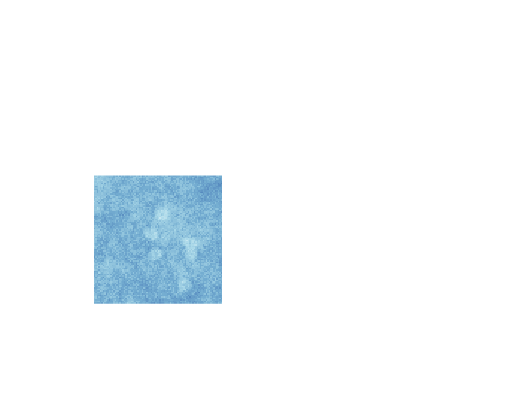

saveas(gcf, fullfile(savepath, '1mM_ROCS_反应前.fig'));

% 反应后-暗场
cutImagesc(tiffpath_before1, 7500, m); clim([2500 6300]);
saveas(gcf, fullfile(savepath, '1mM_ROCS_反应后.tif'));

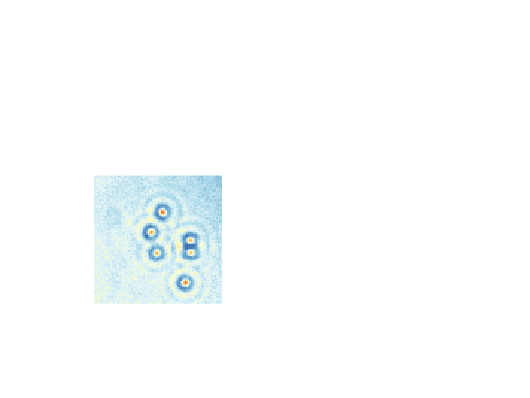

saveas(gcf, fullfile(savepath, '1mM_ROCS_反应后.fig'));

% 反应前-干涉
cutImagesc(tiffpath_before2, 1, m); clim([1650,4400]); 
saveas(gcf, fullfile(savepath, '1mM_干涉_反应前.tif'));

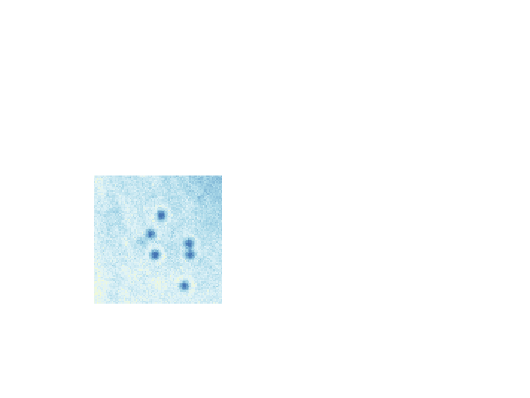

saveas(gcf, fullfile(savepath, '1mM_干涉_反应前.fig'));

% 反应后-干涉
cutImagesc(tiffpath_after, 1, m); clim([1650,4400]); 
saveas(gcf, fullfile(savepath, '1mM_干涉_反应后.tif'));

saveas(gcf, fullfile(savepath, '1mM_干涉_反应后.fig'));

# **AgNS-50uM**

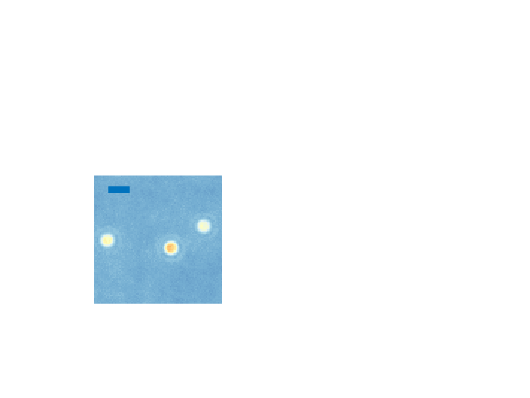

% 反应前的数据
% m = [290 360 35 105];
m = [10 95 230 315];
savepath = "D:\工作汇总\文章\ROCS\我的文章\作图\SI\溶解讨论\AgNS";

% 文件路径
tiffpath_before1 = "F:\work\SPR-DF\Ag-FeCl3\20240125_AgCl溶解\A1_AgNS_50uM_100fps_30mW_150gain_暗场";
tiffpath_before2 = "F:\work\SPR-DF\Ag-FeCl3\20240125_AgCl溶解\A1_干涉_反应前_30mW_150gain";
tiffpath_after = "F:\work\SPR-DF\Ag-FeCl3\20240125_AgCl溶解\A1_干涉_反应后_30mW_150gain";

% 反应前-暗场
cutImagesc(tiffpath_before1, 1, m); clim([2000,13000]); 
line([10 10+1000/68.5], [10 10], 'linewidth', 4)
saveas(gcf, fullfile(savepath, '50uM_ROCS_反应前.tif'));

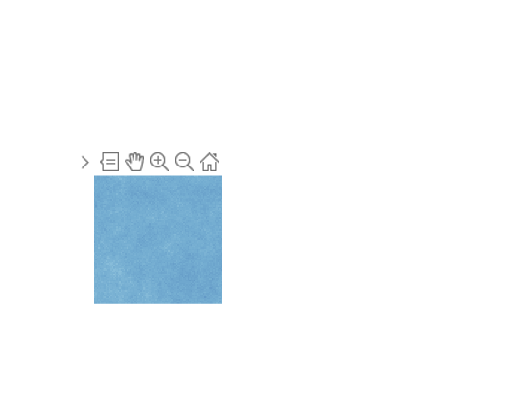

saveas(gcf, fullfile(savepath, '50uM_ROCS_反应前.fig'));

% 反应后-暗场
cutImagesc(tiffpath_before1, 13000, m); clim([2000,13000]); 
saveas(gcf, fullfile(savepath, '50uM_ROCS_反应后.tif'));

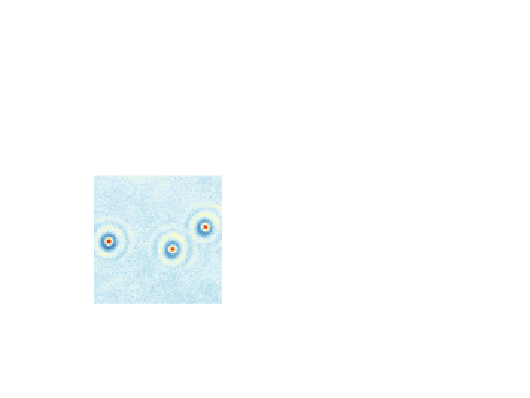

saveas(gcf, fullfile(savepath, '50uM_ROCS_反应后.fig'));

% 反应前-干涉
cutImagesc(tiffpath_before2, 1, m); clim([1300,5250]); 
saveas(gcf, fullfile(savepath, '50uM_干涉_反应前.tif'));

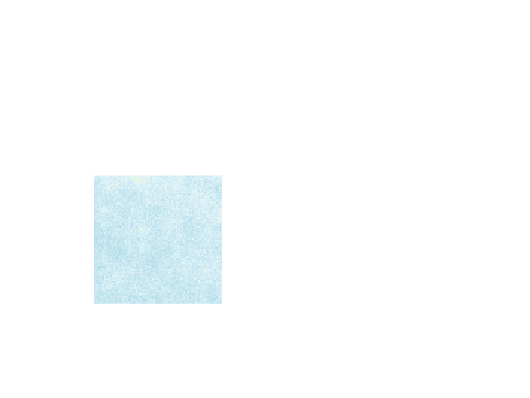

saveas(gcf, fullfile(savepath, '50uM_干涉_反应前.fig'));

% 反应后-干涉
cutImagesc(tiffpath_after, 1, m); clim([1300,5250]); 
saveas(gcf, fullfile(savepath, '50uM_干涉_反应后.tif'));

saveas(gcf, fullfile(savepath, '50uM_干涉_反应后.fig'));

function cutImagesc(tiffpath, ind, m)

    tiffs = dir(fullfile(tiffpath, '*.tiff'));
    I = double(imread(fullfile(tiffpath, tiffs(ind).name)));

    I_cut = cutFig(I, m);
    figure; ax = axes('Units', 'centimeters', 'Position', [2 2 2.7 2.7]);
    imagesc(ax, I_cut);
    axis off; axis equal; colormap(DF_color)
end